clc; close all; clear;

# MARZ 2/3 - Outflow Probe 25 mm from TCC

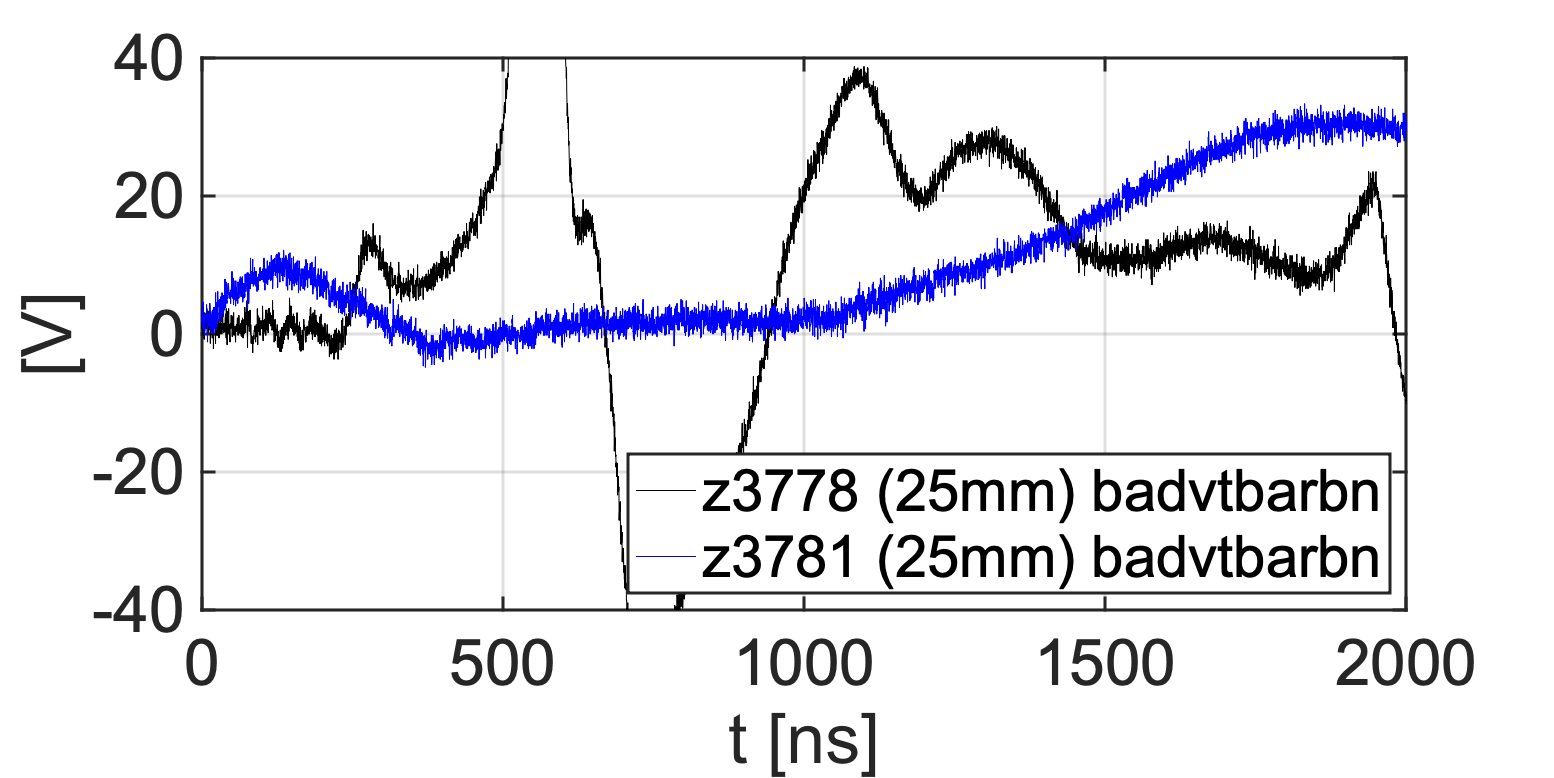

inDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN group/Data/Z/MARZ/Shots/MARZ2_z3778/Inductive Probes/');
fname = 'badvtbarbn';

data = dlmread([inDir,fname]); 

t_z3778 = data(:,1) - 2800e-9; 
y_z3778 = data(:,2);


inDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN group/Data/Z/MARZ/Shots/MARZ3_z3781/Inductive Probes/');
fname = 'badvtbarbn';

data = dlmread([inDir,fname]); 

t_z3781 = data(:,1)  - 2800e-9; 
y_z3781 = data(:,2);

figure
plot(t_z3778*1e9,y_z3778,color='k',DisplayName=['z3778 (25mm) ' fname]); hold on;
plot(t_z3781*1e9,y_z3781,color='b',DisplayName=['z3781 (25mm) ' fname]); hold on;
xlabel('t [ns]');
ylabel('[V]')
grid();
xlim([0,2000])
ylim([-40,40])

formatPlots(900,2);
legend('Location','southeast','box','on')

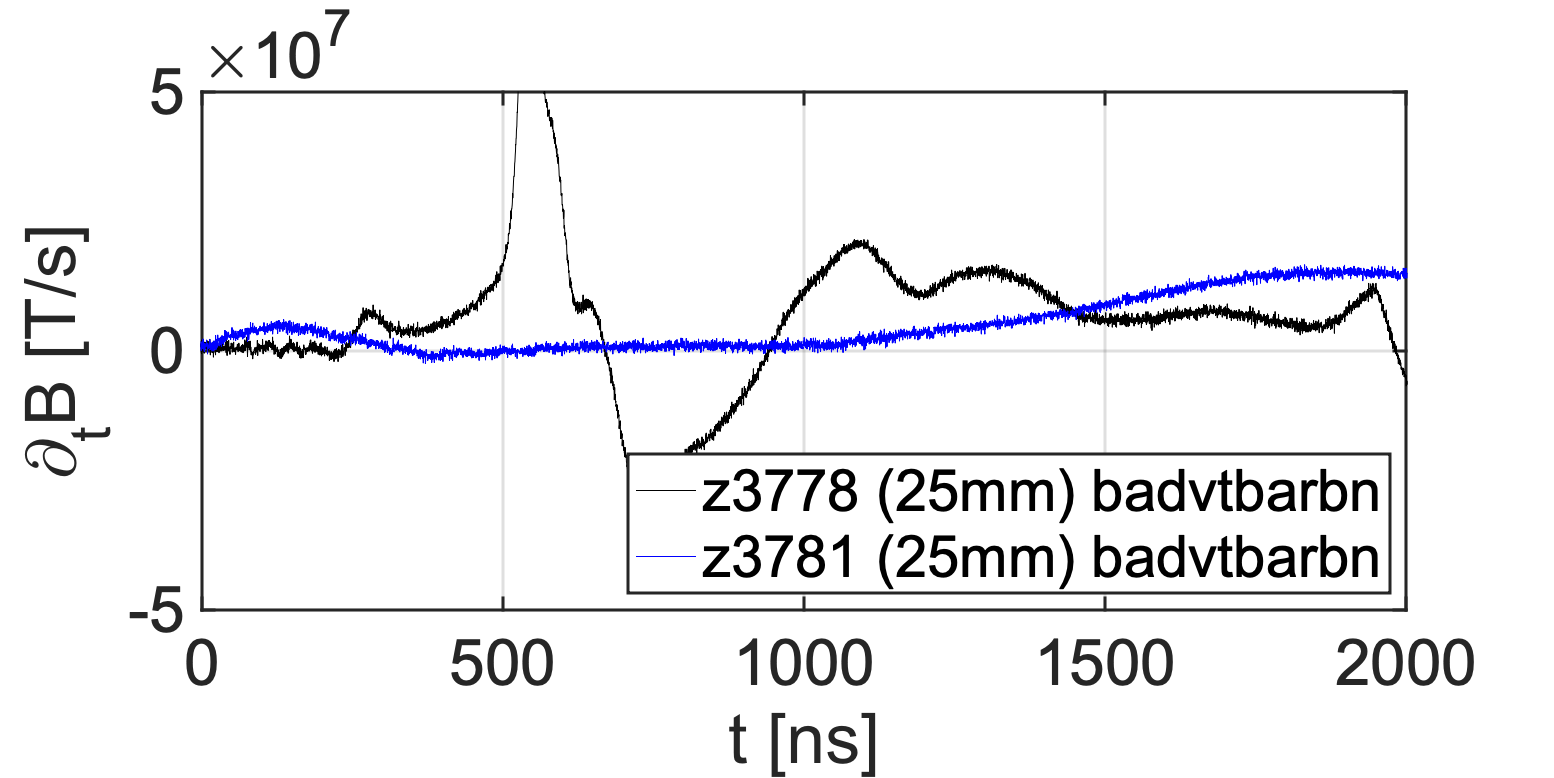

% Calibrate

cal_z3778 = 5.55E+05; 
dtB_z3778 = cal_z3778 * y_z3778; % T/s

cal_z3781 = 4.99E+05; 
dtB_z3781 = cal_z3781 * y_z3781; % T/s




figure
plot(t_z3778*1e9,dtB_z3778,color='k',DisplayName=['z3778 (25mm) ' fname]); hold on;
plot(t_z3781*1e9,dtB_z3781,color='b',DisplayName=['z3781 (25mm) ' fname]); hold on;
xlabel('t [ns]');
ylabel('\partial_tB [T/s]')
grid();
xlim([0,2000]);
ylim([-1,1]*5e7)
formatPlots(900,2);
legend('Location','southeast','box','on')

# Integrate

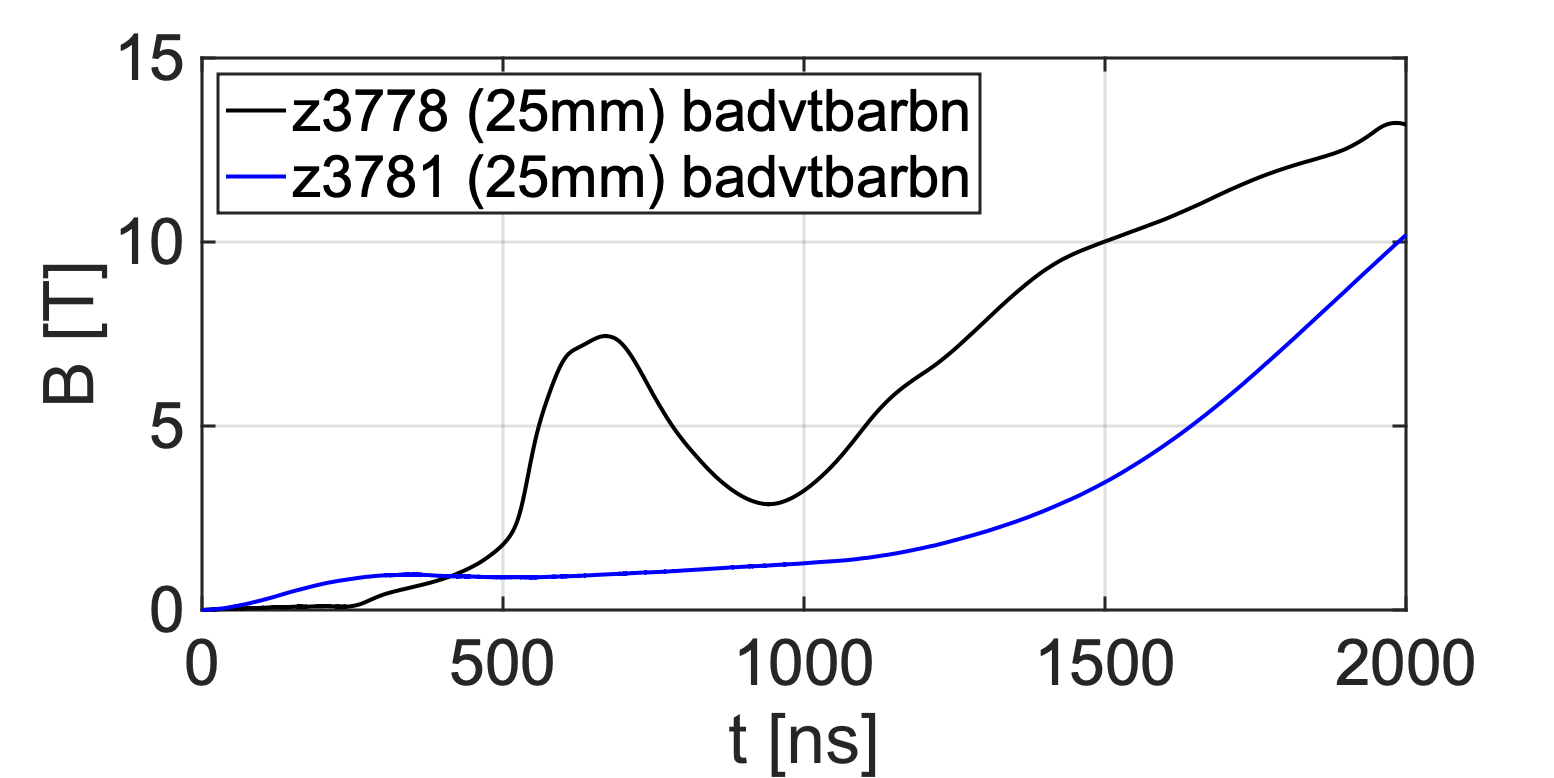

tidx = [0,2000]; % ns
idx1 = (t_z3778 >= tidx(1)*1e-9) & (t_z3778 <= tidx(end)*1e-9);
bdot_z3778 = dtB_z3778(idx1);
B_z3778= cumtrapz(bdot_z3778) * max(diff(t_z3778)); % [T]

idx2 = (t_z3781 >= tidx(1)*1e-9) & (t_z3781 <= tidx(end)*1e-9);
bdot_z3781 = dtB_z3781(idx2);
B_z3781= cumtrapz(bdot_z3781) * max(diff(t_z3781)); % [T]


figure
plot(t_z3778(idx1)*1e9,B_z3778,color='k',linewidth=2,DisplayName=['z3778 (25mm) ' fname]); hold on;
plot(t_z3781(idx2)*1e9,B_z3781,color='b',linewidth=2,DisplayName=['z3781 (25mm) ' fname]); hold on;
xlabel('t [ns]');
ylabel('B [T]')
grid();
xlim([0,2000]);
% ylim([-1,1]*5e7)
formatPlots(900,2);
legend('Location','northwest','box','on')